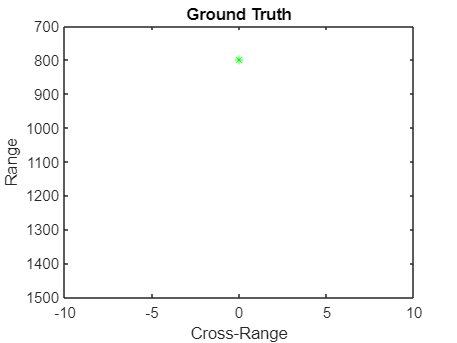

% Author: Kumar Rishav Param Gupta
% Instructor: 
% Based on Project Description Dated: April 20, 2025
% Version: 1 SAR Implementation

close all;
clear;
clc;


c = physconst('LightSpeed'); %Set the physical constant for speed of light.
fc = 4e9; %Set the SAR center frequency.
rangeResolution = 3;  %Set the desired range and cross-range resolution to 3 meters.
crossRangeResolution = 3;
bw = c/(2*rangeResolution); %The signal bandwidth is a parameter derived from the desired range resolution.

%In a SAR system the PRF has dual implications. The PRF not only determines the maximum unambiguous range but also serves as the sampling frequency in the cross-range direction. If the PRF is too low to achieve a higher unambiguous range, there is a longer duration pulses resulting in fewer pulses in a particular region. At the same time, if the PRF is too high, the cross-range sampling is achieved but at the cost of reduced range. Therefore, the PRF should be less than twice the Doppler frequency and should also satisfy the criteria for maximum unambiguous range
prf = 1000; 
aperture = 4;  
tpd = 3*10^-6; 
fs = 120*10^6;

%Configure the LFM signal of the radar.
waveform = phased.LinearFMWaveform('SampleRate',fs, 'PulseWidth', tpd, 'PRF', prf,...
    'SweepBandwidth', bw);

%Assume the speed of aircraft is 100 m/s with a flight duration of 4 seconds.
speed = 100;  
flightDuration = 4;
radarPlatform  = phased.Platform('InitialPosition', [0;-200;1000], 'Velocity', [0; speed; 0]);
slowTime = 1/prf;
numpulses = flightDuration/slowTime +1;

maxRange = 2500;
truncrangesamples = ceil((2*maxRange/c)*fs);
fastTime = (0:1/fs:(truncrangesamples-1)/fs);
% Set the reference range for the cross-range processing.
Rc = 1000;

%Configure the SAR transmitter and receiver. The antenna looks in the broadside direction orthogonal to the flight direction.
antenna = phased.CosineAntennaElement('FrequencyRange', [1e9 6e9]);
antennaGain = aperture2gain(aperture,c/fc); 

transmitter = phased.Transmitter('PeakPower', 50e3, 'Gain', antennaGain);
radiator = phased.Radiator('Sensor', antenna,'OperatingFrequency', fc, 'PropagationSpeed', c);

collector = phased.Collector('Sensor', antenna, 'PropagationSpeed', c,'OperatingFrequency', fc);
receiver = phased.ReceiverPreamp('SampleRate', fs, 'NoiseFigure', 30);

%Configure the propagation channel.
channel = phased.FreeSpace('PropagationSpeed', c, 'OperatingFrequency', fc,'SampleRate', fs,...
    'TwoWayPropagation', true);

%Scene Configuration
%In this example, three static point targets are configured at locations specified below. All targets have a mean RCS value of 1 meter-squared.
%targetpos= [800,0,0;1000,0,0; 1300,0,0]'; 
targetpos= [800,0,0]'; 
%targetvel = [0,0,0;0,0,0; 0,0,0]';
targetvel = [0,0,0]';

%target = phased.RadarTarget('OperatingFrequency', fc, 'MeanRCS', [1,1,1]);
target = phased.RadarTarget('OperatingFrequency', fc, 'MeanRCS', 1);
pointTargets = phased.Platform('InitialPosition', targetpos,'Velocity',targetvel);
% The figure below describes the ground truth based on the target
% locations.
%figure(1);h = axes;plot(targetpos(2,1),targetpos(1,1),'*g');hold all;plot(targetpos(2,2),targetpos(1,2),'*r');hold all;plot(targetpos(2,3),targetpos(1,3),'*b');hold off;
figure(1); clf;
h = axes;plot(targetpos(2,1),targetpos(1,1),'*g');
set(h,'Ydir','reverse');xlim([-10 10]);ylim([700 1500]);
title('Ground Truth');ylabel('Range');xlabel('Cross-Range');

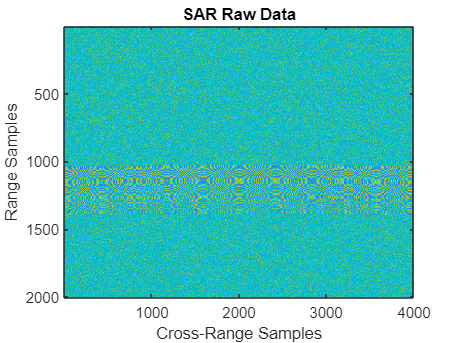


%SAR Signal Simulation
%The following section describes how the system operates based on the above configuration. Specifically, the section below shows how the data collection is performed for a SAR platform. As the platform moves in the cross-range direction, pulses are transmitted and received in directions orthogonal to the flight path. A collection of pulses gives the phase history of the targets lying in the illumination region as the platform moves. The longer the target lies in the illumination region, the better the cross-range resolution for the entire image because the process of range and cross-range focusing is generalized for the entire scene.
% Define the broadside angle
refangle = zeros(1,size(targetpos,2));

% Environmental conditions
weatherCondition = 'clear'; % Options: 'clear', 'lightRain', 'heavyRain', 'fog', 'snow'

switch weatherCondition
    case 'clear'
        lossPerKm = 0;
    case 'lightRain'
        lossPerKm = 0.02;
    case 'heavyRain'
        lossPerKm = 0.3;
    case 'fog'
        lossPerKm = 0.03;
    case 'snow'
        lossPerKm = 0.1;
end

rxsig = zeros(truncrangesamples,numpulses);
for ii = 1:numpulses
    % Update radar platform and target position
    [radarpos, radarvel] = radarPlatform(slowTime);
    [targetpos,targetvel] = pointTargets(slowTime);
    
    % Get the range and angle to the point targets
    [targetRange, targetAngle] = rangeangle(targetpos, radarpos);
    
    % Generate the LFM pulse
    sig = waveform();
    % Use only the pulse length that will cover the targets.
    sig = sig(1:truncrangesamples);
    
    % Transmit the pulse
    sig = transmitter(sig);
    
    % Define no tilting of beam in azimuth direction
    targetAngle(1,:) = refangle;
    
    % Radiate the pulse towards the targets
    sig = radiator(sig, targetAngle);
    
    % Propagate the pulse to the point targets in free space
    sig = channel(sig, radarpos, targetpos, radarvel, targetvel);

    % Apply atmospheric attenuation
    sig = applyAtmosphericLoss(sig, targetRange, lossPerKm);
    
    % Reflect the pulse off the targets
    sig = target(sig);
    
    % Collect the reflected pulses at the antenna
    sig = collector(sig, targetAngle);
    
    % Receive the signal  
    rxsig(:,ii) = receiver(sig);
    
end

%Visualize the received signal. The received signal can now be visualized as a collection of multiple pulses transmitted in the cross-range direction. The plots show the real part of the signal for the three targets. The range and cross-range chirps can be seen clearly. The target responses can be seen as overlapping as the pulse-width is kept longer to maintain average power.
figure(2); clf;
imagesc(real(rxsig));title('SAR Raw Data');
xlabel('Cross-Range Samples')
ylabel('Range Samples')

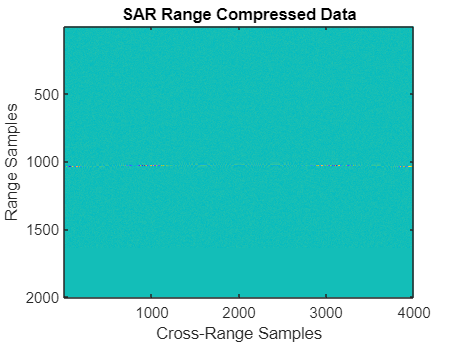


%Perform range compression. Each row of the received signal, which contains all the information from each pulse, can be matched filtered to get the dechirped or range compressed signal.
pulseCompression = phased.RangeResponse('RangeMethod', 'Matched filter', 'PropagationSpeed', c, 'SampleRate', fs);
matchingCoeff = getMatchedFilter(waveform);
[cdata, rnggrid] = pulseCompression(rxsig, matchingCoeff);

%This figure shows the response after matched filtering has been performed on the received signal. The phase histories of the three targets are clearly visible along the cross-range direction and range focusing has been achieved.
figure(3); clf;
imagesc(real(cdata));title('SAR Range Compressed Data');
xlabel('Cross-Range Samples')
ylabel('Range Samples')

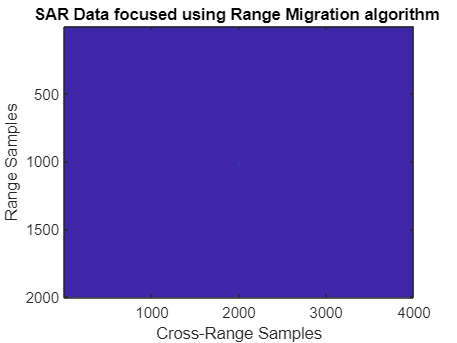


%Perform azimuth Compression. There are multiple techniques to process the cross-range data and get the final image from the SAR raw data once range compression has been achieved. In essence, range compression helps achieve resolution in the fast-time or range direction and the resolution in the cross-range direction is achieved by azimuth or cross-range compression. Two such techniques are the range migration algorithm and the back-projection algorithm, which are demonstrated in this example.
rma_processed = helperRangeMigration(cdata,fastTime,fc,fs,prf,speed,numpulses,c,Rc);
bpa_processed = helperBackProjection(cdata,rnggrid,fastTime,fc,fs,prf,speed,crossRangeResolution,c);

%Visualize the final SAR image. Plot the focused SAR image using the range migration algorithm and the approximate back projection algorithm. Only a section of the image formed via the range migration algorithm is shown to accurately point the location of the targets.
%The range migration and accurate form of the backprojection algorithm as shown by [2] and [3] provides theoretical resolution in the cross-track as well as along-track direction. Since the back-projection used here is of the approximate form, the spread in azimuth direction is evident in case of the back-projection, whereas the data processed via range migration algorithm shows that theoretical resolution is achieved.
figure(4); clf;
imagesc((abs((rma_processed.'))));
title('SAR Data focused using Range Migration algorithm ')
xlabel('Cross-Range Samples')
ylabel('Range Samples')

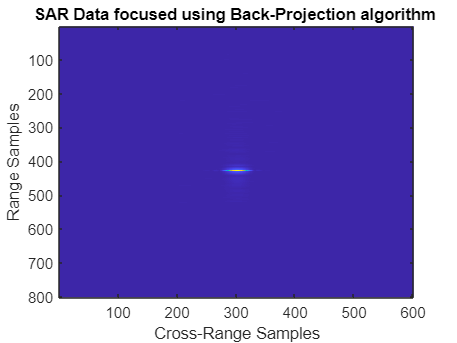

figure(5); clf;
imagesc((abs(bpa_processed(600:1400,1700:2300))));
title('SAR Data focused using Back-Projection algorithm ')
xlabel('Cross-Range Samples')
ylabel('Range Samples')


%{
Summary
This example shows how to develop SAR processing leveraging a LFM signal in an airborne data collection scenario. The example also shows how to generate an image from the received signal via range migration and approximate form of the back-projection algorithms.
References
Cafforio, C., C. Prati, and F. Rocca. “SAR Data Focusing Using Seismic Migration Techniques.” IEEE Transactions on Aerospace and Electronic Systems 27, no. 2 (March 1991): 194–207. https://doi.org/10.1109/7.78293.
Cumming, I., and J. Bennett. “Digital Processing of Seasat SAR Data.” In ICASSP ’79. IEEE International Conference on Acoustics, Speech, and Signal Processing, 4:710–18. Washington, DC, USA: Institute of Electrical and Electronics Engineers, 1979. https://doi.org/10.1109/ICASSP.1979.1170630.
Yibo Na, Yilong Lu, and Hongbo Sun. “A Comparison of Back-Projection and Range Migration Algorithms for Ultra-Wideband SAR Imaging.” In Fourth IEEE Workshop on Sensor Array and Multichannel Processing, 2006., 320–24. Waltham, Massachusetts, USA: IEEE, 2006. https://doi.org/10.1109/SAM.2006.1706146.
Yegulalp, A. F. “Fast Backprojection Algorithm for Synthetic Aperture Radar.” In Proceedings of the 1999 IEEE Radar Conference. Radar into the Next Millennium (Cat. No.99CH36249), 60–65. Waltham, MA, USA: IEEE, 1999. https://doi.org/10.1109/NRC.1999.767270.
%}


%Appendix
%Range Migration Algorithm

function azcompresseddata = helperRangeMigration(sigData,fastTime,fc,fs,prf,speed,numPulses,c,Rc)
%This function demonstrates the range migration algorithm for imaging the side-looking synthetic aperture radar. The pulse compressed synthetic aperture data is considered in this algorithm.

%Set the range frequency span.
frequencyRange = linspace(fc-fs/2,fc+fs/2,length(fastTime));
krange = 2*(2*pi*frequencyRange)/c;

%Set the cross-range wavenumber.
kaz = 2*pi*linspace(-prf/2,prf/2,numPulses)./speed;

%Generate a matrix of the cross-range wavenumbers to match the size of the received two-dimensional SAR signal.
kazimuth = kaz.';
kx = krange.^2-kazimuth.^2;

%Set the final wavenumber to achieve azimuth focusing.
kx = sqrt(kx.*(kx > 0));
kFinal = exp(1i*kx.*Rc);

%Perform a two-dimensional FFT on the range compressed signal.
sdata =fftshift(fft(fftshift(fft(sigData,[],1),1),[],2),2);

%Perform bulk compression to get the azimuth compression at the reference range. Perform filtering of the 2-D FFT signal with the new cross-range wavenumber to achieve complete focusing at the reference range and as a by-product, partial focusing of targets not lying at the reference range.
fsmPol = (sdata.').*kFinal;

%Perform Stolt interpolation to achieve focusing for targets that are not lying at the reference range.
stoltPol = fsmPol;
for i = 1:size((fsmPol),1)
    stoltPol(i,:) = interp1(kx(i,:),fsmPol(i,:),krange(1,:));
end
stoltPol(isnan(stoltPol)) = 1e-30;
stoltPol = stoltPol.*exp(-1i*krange.*Rc);
azcompresseddata = ifft2(stoltPol);
end


%Back-Projection Algorithm
function data = helperBackProjection(sigdata,rnggrid,fastTime,fc,fs,prf,speed,crossRangeResolution,c)
%This function demonstrates the time-domain back projection algorithm for imaging the side-looking synthetic aperture radar. The pulsed compressed synthetic aperture data is taken as input in this algorithm. Initialize the output matrix.
data = zeros(size(sigdata));
azimuthDist = -200:speed/prf:200;%azimuth distance
%Limit the range and cross-range pixels being processed to reduce processing time.
rangelims = [700 1400];
crossrangelims = [-10 10];
%Index the range grid in accordance with the range limits.
rangeIdx =  [find(rnggrid>rangelims(1), 1) find(rnggrid<rangelims(2),1,'last')];
%Index the azimuth distance in accordance with the cross-range limits.
crossrangeIdxStart = find(azimuthDist>crossrangelims(1),1);
crossrangeIdxStop = find(azimuthDist<crossrangelims(2),1,'last');
for i= rangeIdx(1):rangeIdx(2)  % Iterate over the range indices
    
    % Using desired cross-range resolution, compute the synthetic aperture
    % length
    lsynth= (c/fc)* (c*fastTime(i)/2)/(2*crossRangeResolution);
    lsar = round(lsynth*length(azimuthDist)/azimuthDist(end)) ;
    % Ensure lsar is an odd number
    lsar = lsar + mod(lsar,2);    
    
    % Construct hanning window for cross-range processing, to suppress the
    % azimuthal side lobes
    hn= hanning(lsar).';
    % Iterate over the cross-range indices
    for j= crossrangeIdxStart:crossrangeIdxStop 
        % azimuth distance in x direction over cross-range indices
        posx= azimuthDist(j);
        % range in y-direction over range indices
        posy= c*fastTime(i)/2;
        % initializing count to zero
        count= 0;
        % Iterate over the synthetic aperture
        for k= j-lsar/2 +1:j+ lsar/2 
            % Time delay for each of range and cross-range indices
            td= sqrt((azimuthDist(k)- posx)^2 + posy^2)*2/c;
            cell= round(td*fs) +1 ;
            signal = sigdata(cell,k);
            count= count + hn(k -(j-lsar/2))*signal *exp(1j*2*pi*fc*(td));
        end
        % Processed data at each of range and cross-range indices
        data(i,j)= count;
    end
    
end
end

% Environmental Loss Function (in dB)
function attenuatedSig = applyAtmosphericLoss(signal, range, lossPerKm)
    % Applies two-way signal attenuation due to environmental effects.
    % signal: input radar signal
    % range: slant range to target (vector or scalar)
    % lossPerKm: attenuation in dB/km
    
    % Compute total loss in dB for two-way path
    totalLoss_dB = 2 * lossPerKm * (range / 1e3);  % Two-way attenuation
    totalLoss_linear = 10^(-totalLoss_dB / 20);    % Convert to linear scale
    attenuatedSig = signal * totalLoss_linear;
end
%}